# Batch Chemical Reactor Design

Chemical reactor is a vessel in which chemical reaction is carried out. Batch reactor is a type of non-continuous chemical reactor. In batch reactor, the feeds are fed (charged) into the reactor vessel only at the begining of reaction. No output is drawn from the reactor untill the batch time has reached.

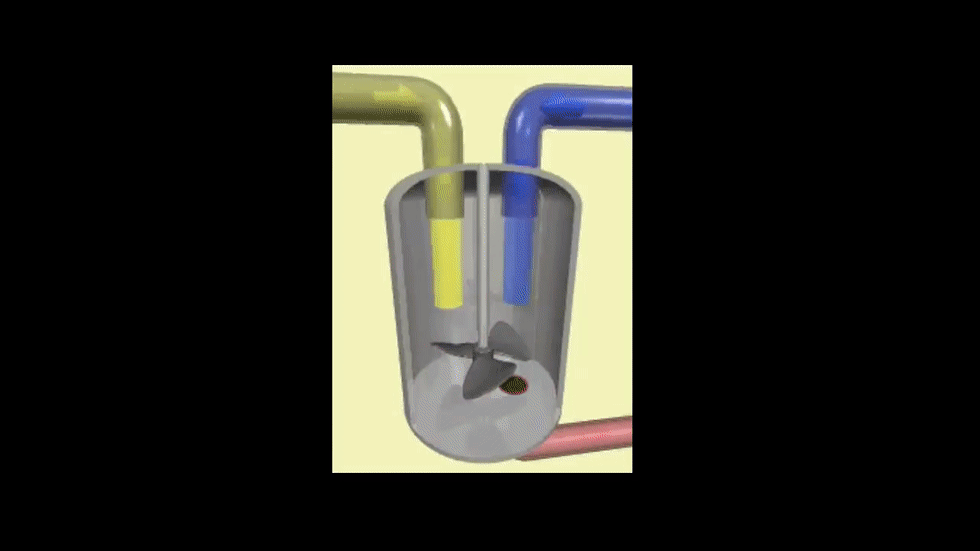

The contents of the reactor is completely mixed and hence are homogeneous. 

The temperature is maintained by a cooling Jacket or heating coil.

### Component mass balance of specied A


$$\begin{array}{l}
\textrm{Input}\;\textrm{flowrate}=\textrm{Output}\;\textrm{flowrate}+\textrm{Accumulation}\;\textrm{in}\;\textrm{Reactor}+\textrm{Dissapearance}\;\textrm{by}\;\textrm{Reaction}\\
\;\\
\Rightarrow \;\;0\;=\;0+\frac{{\textrm{dN}}_{\mathrm{A}} }{\textrm{dt}}+\mathrm{V}\left(-{\mathrm{r}}_{\mathrm{A}} \right)\\
\;\\
\Rightarrow \;\;\;\mathrm{t}=-\int_{{\mathrm{N}}_{\mathrm{A},\mathrm{o}} }^{{\mathrm{N}}_{\mathrm{A}} } \frac{1}{\mathrm{V}}\frac{{\textrm{dN}}_{\mathrm{A}} }{\left(-{\mathrm{r}}_{\mathrm{A}} \right)}\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\\
\Rightarrow \;\;\;\mathrm{t}=\int_0^{\chi_{\mathrm{A}} } \frac{1}{\mathrm{V}}\frac{{\mathrm{d}\chi }_{\mathrm{A}} }{\left(-{\mathrm{r}}_{\chi_{\mathrm{A}} } \right)}\;\;\\
\;\\
\textrm{Here},\\
\;\\
{\mathrm{N}}_{\mathrm{A}} =\textrm{moles}\;\textrm{of}\;\mathrm{A},\;\textrm{gmol}\\
{\mathrm{N}}_{\mathrm{A},\mathrm{o}} =\textrm{moles}\;\textrm{of}\;\mathrm{A}\;\textrm{initially}\;\textrm{fed}\;\textrm{to}\;\textrm{reactor},\;\textrm{gmol}\\
-{\mathrm{r}}_{\mathrm{A}} =\textrm{rate}\;\textrm{of}\;\textrm{dissapearance}\;\textrm{of}\;\mathrm{A},\frac{\textrm{mol}}{\textrm{Ls}}\\
\mathrm{t}=\textrm{time},\mathrm{s}\\
\mathrm{V}=\textrm{Volume}\;\textrm{of}\;\textrm{the}\;\textrm{reactor},\mathrm{L}\\
\chi_{\mathrm{A}} =\frac{{{\mathrm{N}}_{\mathrm{A},\mathrm{o}} -\mathrm{N}}_{\mathrm{A}} }{{\mathrm{N}}_{\mathrm{A},\mathrm{o}} }=\textrm{conversion}\;\textrm{of}\;\mathrm{A}
\end{array}$$


## Sample Reaction


$$\mathrm{A}\to \mathrm{B}\iff \mathrm{C}$$


#### Rates of reactions


$$\begin{array}{l}
{\mathrm{r}}_{\mathrm{A}} =-\frac{\textrm{dA}}{\textrm{dt}}{\;\;=\;\mathrm{k}}_1 \mathrm{A}\\
{\mathrm{r}}_{\mathrm{B}} =\;-\frac{\textrm{dB}}{\textrm{dt}}\;={\mathrm{k}}_2 \mathrm{B}-{\mathrm{k}}_1 \mathrm{A}-{\mathrm{k}}_4 \mathrm{C}\\
{\mathrm{r}}_{\mathrm{C}} =\;-\frac{\textrm{dC}}{\textrm{dt}}\;={\mathrm{k}}_4 \mathrm{C}-{\mathrm{k}}_3 \mathrm{B}
\end{array}$$


## Solution

clear all

#### Step 1: setup known variables

[k1, k2, k3, k4]= deal(1e-2, 5e-3, 3e-3, 1e-3); % 1/s
A0=100; % mol_A/m^3
B0=0; % mol_B/m^3
C0=0 % mol_C/m^3

C0 = 0

#### Step 2: Declare rate equations

rA = @(A) -k1*A

rA = function_handle with value:
    @(A)-k1*A


rB = @(A,B,C) -(k2*B - k1*A - k4*C)

rB = function_handle with value:
    @(A,B,C)-(k2*B-k1*A-k4*C)


rC = @(B,C) -(k4*C - k3*B)

rC = function_handle with value:
    @(B,C)-(k4*C-k3*B)


#### Step 4: Solve the equations

rx = @(t, conc) ...
...
[rA(conc(1))
 rB(conc(1), conc(2), conc(3))
 rC(conc(2), conc(3))];
sol = ode45(rx, 0:1:1000, [A0; B0; C0])

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 2.0095e-04 0.0012 0.0062 0.0313 0.1569 0.7849 3.9248 19.6241 51.3626 97.3951 157.4026 231.0697 309.9891 388.6109 467.2495 545.8872 624.5249 703.1626 781.8003 860.4380 939.0757 1000]
          y: [3×23 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


#### STEP 5: Plot the solution

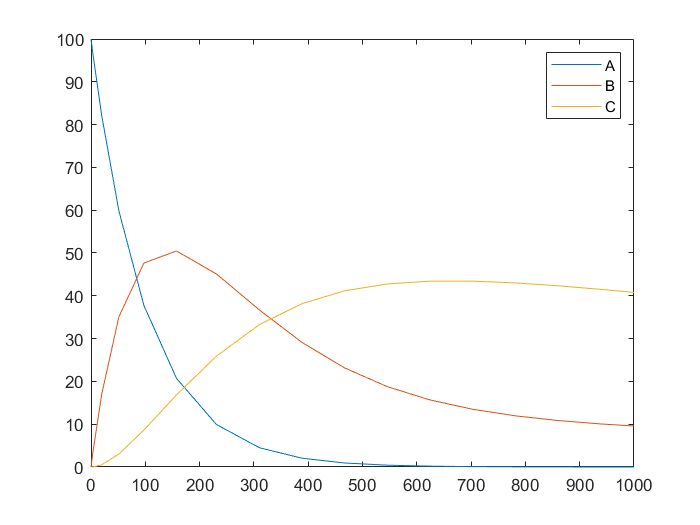

plot(sol.x, sol.y);
legend A B C

Find operating time required for maximum concentration of component

- B

- C

operatingTime = 0:1000;
concProf = deval(sol,operatingTime);
concProf_A = concProf()

Unrecognized function or variable 'A'.

concProf_B = double(B(operatingTime));
concProf_C = double(C(operatingTime));

% Find local maxima
maxB = islocalmax(ConcProf_B);

% Visualize results
clf
plot(ConcProf_B,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

% Plot local maxima
plot(find(maxB),ConcProf_B(maxB),'^','Color',[217 83 25]/255,...
    'MarkerFaceColor',[217 83 25]/255,'DisplayName','Local maxima')
title(['Number of extrema: ' num2str(nnz(maxB))])
hold off
legend